## CIV102 Matboard Bridge Design Project - Supporting Calculations

#### By: Matthew Oliveira, Joyce Shen, Andy Cai

------------------------------------------------------------------------------------------------------------------------------------------

**Initialization and Inputing the Bridge Dimensions**

%Initialize overall bridge geometry (side profile) and provide a force profile

n = 1280; %Number of locations to check for failure along the bridge
L = 1280; %Length of the bridge (in millimeters)
force_profile = zeros(1,n); %This matrix will hold all the external forces acting on the bridge

%Initialize the cross-sectional properties of the Bridge across the length

%Cross-section matrices are formatted as:
% [height, width_bottom, width_top, layers_of_top, layers_of_bottom, layers_of_side, glue_tab_length]

cross_section_1 = [75, 80, 100, 1, 1, 1, 10];

bridge_profile = NaN(n, 7);

for p = 1:n
    bridge_profile(p,:) = cross_section_1;
end


%Initialize the material properties of the bridge

tensile_strength = 30;
compressive_strength = 6;
shear_strength = 4;
youngs_modulus = 4000;
poissons_ratio = 0.2;
contact_cement_shear_strength = 2;

**Calculations**

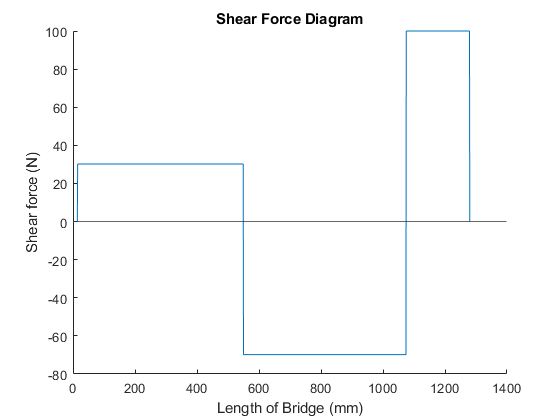

%We will calculate the SFD and BMD and graph these

[SFD, BMD, force_profile] = ApplyPL(550, 100, force_profile, n);
[SFD, BMD, force_profile] = ApplyPL(n, 100, force_profile, n);

x = linspace(1,n, n);

figure
hold on;
plot(x, SFD)
title("Shear Force Diagram")
xlabel("Length of Bridge (mm)")
ylabel("Shear force (N)")
yline(0)
hold off

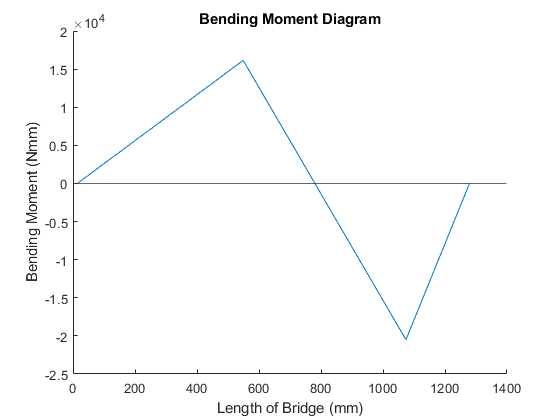


figure
hold on;
plot(x, BMD)
title("Bending Moment Diagram")
xlabel("Length of Bridge (mm)")
ylabel("Bending Moment (Nmm)")
yline(0)
hold off

%We will calculate the cross-sectional properties of our design

[I, y, Q, QGlue, b] = SectionProperties(cross_section_1)

Q = 6.1740e+03

I = 4.1248e+05

y = 41.4687

Q = 6.1740e+03

QGlue = 4.1798e+03

b = 2.5400


%We then make an array to hold the cross-sectional properties for the
%regions of the bridge where they are true

section_properties = NaN(n, 6);

for j = 1:n
    section_properties(j, :) = [j, I, y, Q, QGlue, b];
end


%We get a matrix containing the shear failure at every point x along the
%bridge
[V_shear_failure, V_shear_failure_glue] = Vfail(section_properties, shear_strength, contact_cement_shear_strength, n)

V_shear_failure =   678.7827  678.7827  678.7827  678.7827  678.7827  678.7827  678.7827  678.7827  678.7827  678.7827  678.7827  678.7827  678.7827  678.7827  678.7827  678.7827  678.7827  678.7827  678.7827  678.7827  678.7827  678.7827  678.7827  678.7827  678.7827  678.7827  678.7827  678.7827  678.7827  678.7827  678.7827  678.7827  678.7827  678.7827  678.7827  678.7827  678.7827  678.7827  678.7827  678.7827  678.7827  678.7827  678.7827  678.7827  678.7827  678.7827  678.7827  678.7827  678.7827  678.7827


V_shear_failure_glue =   501.3135  501.3135  501.3135  501.3135  501.3135  501.3135  501.3135  501.3135  501.3135  501.3135  501.3135  501.3135  501.3135  501.3135  501.3135  501.3135  501.3135  501.3135  501.3135  501.3135  501.3135  501.3135  501.3135  501.3135  501.3135  501.3135  501.3135  501.3135  501.3135  501.3135  501.3135  501.3135  501.3135  501.3135  501.3135  501.3135  501.3135  501.3135  501.3135  501.3135  501.3135  501.3135  501.3135  501.3135  501.3135  501.3135  501.3135  501.3135  501.3135  501.3135


%Calculate the force that would cause the bridge to fail via shear buckling
[V_shear_buckling_failure] = VfailBuck(section_properties, bridge_profile, force_profile, youngs_modulus, poissons_ratio, n)

V_shear_buckling_failure =   798.6439  798.6439  798.6439  798.6439  798.6439  798.6439  798.6439  798.6439  798.6439  798.6439  798.6439  798.6439  798.6439  798.6439  798.6439  798.6439  798.6439  798.6439  798.6439  798.6439  798.6439  798.6439  798.6439  798.6439  798.6439  798.6439  798.6439  798.6439  798.6439  798.6439  798.6439  798.6439  798.6439  798.6439  798.6439  798.6439  798.6439  798.6439  798.6439  798.6439  798.6439  798.6439  798.6439  798.6439  798.6439  798.6439  798.6439  798.6439  798.6439  798.6439


%Calculate the moment that would cause the bridge to fail via compression or tension at any point
[moment_of_failure_tension, moment_of_failure_compression] = Mfailure(section_properties, bridge_profile, tensile_strength, compressive_strength, BMD, n)

moment_of_failure_tension = 	1.0e+05 *

    3.6904    3.6904    3.6904    3.6904    3.6904    3.6904    3.6904    3.6904    3.6904    3.6904    3.6904    3.6904    3.6904    3.6904    2.9841    2.9841    2.9841    2.9841    2.9841    2.9841    2.9841    2.9841    2.9841    2.9841    2.9841    2.9841    2.9841    2.9841    2.9841    2.9841    2.9841    2.9841    2.9841    2.9841    2.9841    2.9841    2.9841    2.9841    2.9841    2.9841    2.9841    2.9841    2.9841    2.9841    2.9841    2.9841    2.9841    2.9841    2.9841    2.9841


moment_of_failure_compression = 	1.0e+04 *

    5.9681    5.9681    5.9681    5.9681    5.9681    5.9681    5.9681    5.9681    5.9681    5.9681    5.9681    5.9681    5.9681    5.9681    7.3808    7.3808    7.3808    7.3808    7.3808    7.3808    7.3808    7.3808    7.3808    7.3808    7.3808    7.3808    7.3808    7.3808    7.3808    7.3808    7.3808    7.3808    7.3808    7.3808    7.3808    7.3808    7.3808    7.3808    7.3808    7.3808    7.3808    7.3808    7.3808    7.3808    7.3808    7.3808    7.3808    7.3808    7.3808    7.3808


%Calculate the moment that would cause the bridge to buckle at any point
%along its length
[moment_of_buckling] = MfailBuck(section_properties, youngs_modulus, poissons_ratio, BMD, bridge_profile, n)

moment_of_buckling = 	1.0e+04 *

    5.4394    5.4394    5.4394    5.4394    5.4394    5.4394    5.4394    5.4394    5.4394    5.4394    5.4394    5.4394    5.4394    5.4394    5.4394    5.4394    5.4394    5.4394    5.4394    5.4394    5.4394    5.4394    5.4394    5.4394    5.4394    5.4394    5.4394    5.4394    5.4394    5.4394    5.4394    5.4394    5.4394    5.4394    5.4394    5.4394    5.4394    5.4394    5.4394    5.4394    5.4394    5.4394    5.4394    5.4394    5.4394    5.4394    5.4394    5.4394    5.4394    5.4394


**Functions for Calculations**

function [SFD, BMD, force_profile] = ApplyPL(point, force, force_profile, n)
%Construct and SFD and BMD from the application of a point load
%Force represents the magnitude of the load, point the location, and
%force_profile the past loads applied to the structure
%n is the length of the bridge

%We define the positive direction of force as upward, and the negative
%direction as downward.  force_profile should only contain negative forces

%We will keep our supports at 15mm and 1075mm
support_A_position = 15;
support_B_position = 1075;

%We now add the force of magnititude |force| to our force profile (pointing
%downwards)
force_profile(point) = -1 * force;

%We take the sum of the moments around support A (should be equal to zero)
%and use this to calculate the reaction force at support B
moment_about_A = 0;

for pos = support_A_position:n
    if force_profile(pos) ~= 0
        moment_about_A = moment_about_A + (pos-support_A_position) * force_profile(pos);
    end
end

force_at_B = -1 .* moment_about_A / (support_B_position - support_A_position);

%Now, because the sum of the forces in the y-direction must be zero, we can
%solve for the reaction force at support A

remaining_downward_force = force_at_B + sum(force_profile);

force_at_A = -1 * remaining_downward_force;

%We make a temporary force profile copy to help with our solution
temp_force_profile = force_profile;

temp_force_profile(support_A_position) = temp_force_profile(support_A_position) + force_at_A;
temp_force_profile(support_B_position) = temp_force_profile(support_B_position) + force_at_B;

SFD = force_profile .* 0;
BMD = force_profile .* 0;

%First we generate a matrix for our SFD
for pos = 2:n
    
    if SFD(pos - 1) ~= 0
        if temp_force_profile(pos) == 0
            SFD(pos) = SFD(pos-1);
        else
            SFD(pos) = SFD(pos-1) + temp_force_profile(pos);
        end
    else
        if temp_force_profile(pos) == 0
            SFD(pos) = SFD(pos-1);
        else
            SFD(pos) = SFD(pos-1) + temp_force_profile(pos);
        end
    end
    
end

%Now we use our SFD matrix to generate a BMD matrix
for pos = 2:n
    
    BMD(pos) = BMD(pos-1) + SFD(pos);
end

end

function [I, y, Q, QGlue, b] = SectionProperties(properties_matrix)
%Input: A matrix containing the geometric properties of the cross-section
%in the format: [height, width_bottom, width_top, layers_of_top, layers_of_side, layers_of_bottom,
% glue_tab_length]
%Output: Sectional Properties for the cross-section

height = properties_matrix(1);
width_bottom = properties_matrix(2);
width_top = properties_matrix(3);
layers_of_top = properties_matrix(4);
layers_of_bottom = properties_matrix(5);
layers_of_side = properties_matrix(6);
glue_tab_length = properties_matrix(7);

%We make rectangles to describe each part of the cross-section
%in the format [height, width]
base_rectangle = [1.27 * layers_of_bottom, width_bottom];
web_rectangle = [height - (1.27 * layers_of_bottom) - (1.27 * layers_of_top) - 1.27, 1.27 * layers_of_side];
glue_tab_rectangle = [1.27, glue_tab_length];
top_rectangle = [1.27 * layers_of_top, width_top];

%First we collect the y, I and A values for each of the individual
%rectangles of the cross-section
I_base = (base_rectangle(1)^3 * (base_rectangle(2)))/12;
y_base = (base_rectangle(1)) / 2;
A_base = base_rectangle(1) * base_rectangle(2);

I_web = (web_rectangle(1)^3 * web_rectangle(2))/12;
y_web = (base_rectangle(1) + web_rectangle(1)/2);
A_web = (web_rectangle(1) * web_rectangle(2));

I_tab = (glue_tab_rectangle(1)^3 * glue_tab_rectangle(2)) /12;
y_tab = (base_rectangle(1) + web_rectangle(1) + glue_tab_rectangle(1)/2);
A_tab = (glue_tab_rectangle(1) * glue_tab_rectangle(2));

I_top = (top_rectangle(1)^3 * top_rectangle(2))/12;
y_top = (top_rectangle(1) / 2 + web_rectangle(1) + glue_tab_rectangle(1) + base_rectangle(1));
A_top = top_rectangle(1) * top_rectangle(2);

%Now we can calculate our I, y and Q values
y = (A_base * y_base + 2 * A_web * y_web + 2 * A_tab * y_tab + A_top * y_top)/(A_base + 2 * A_web + 2 * A_tab + A_top);

I = I_base + (y-y_base)^2 * A_base + 2 * (I_web + (y-y_web)^2 * A_web) + 2 * (I_tab + (y-y_tab)^2 * A_tab) + I_top + (y-y_top)^2 * A_top;

Q = (y - y_base) * A_base + 2 * (y - (base_rectangle(1) + web_rectangle(1)/4)) * (web_rectangle(1) * web_rectangle(2) / 2 )

QGlue = (y_top - y) * A_top + 2;

b = 2 * web_rectangle(2);
end

function [V_shear_failure, V_shear_failure_glue] = Vfail(section_properties, shear_strength, contact_cement_shear_strength, n)
%Input: section_properties is a matrix formatted:[x, I, y, Q, QGlue, b],
%and 
%Output: V_shear_failure and V_shear_failure_glue are matrices that give
%the failure load for shear at every x.

for d = 1:n
    V_shear_failure(d) = (shear_strength * section_properties(d, 2) * section_properties(d, 6)) / section_properties(d, 4);
    V_shear_failure_glue(d) = (contact_cement_shear_strength * section_properties(d, 2) * section_properties(d, 6)) / section_properties(d, 5);
end

end

function [V_shear_buckling_failure] = VfailBuck(section_properties, bridge_profile, force_profile, youngs_modulus, poissons_ratio, n)
%Input: Cross-sectional properties, the poisson's ratio, the bridge's
%cross-section profile, and the youngs modulus
%Output: The shear force that results in shear buckling failure for each
%point

support_A_position = 15;
support_B_position = 1075;

%First find the largest distance between a support and applied force and
%call this d

d = 0;

for i = 1:n
    if force_profile(i) ~= 0
        b = min(abs(i - support_A_position), abs(i-support_B_position));
        if b > d
            d = b;
        end
    end
end

%Now we find the distance between webs for the different cross-sections
%across the bridge

a = NaN(n,1);

for j = 1:n
    a(j) = abs(bridge_profile(j, 2) - 2 * bridge_profile(j, 6) * 1.27);
end

%Now we calculate the shear strength that would lead to failure

shear_stress = NaN(n, 1);

for i = 1:n
    shear_stress(i) = ((5 * pi^2 * youngs_modulus) / (12 * (1-poissons_ratio^2))) * ((1.27 * bridge_profile(i, 6)/ a(i))^2 + (1.27 *  bridge_profile(i, 6)/ d)^2);
end

for d = 1:n
    V_shear_buckling_failure(d) = (shear_stress(d) * section_properties(d, 2) * section_properties(d, 6)) / section_properties(d, 4);
end


end

function [moment_of_failure_tension, moment_of_failure_compression] = Mfailure(section_properties, bridge_profile, tensile_strength, compressive_strength, BMD, n)
%Input: The bending moment diagram, maximum tensile and compressive
%strengths, and the section_properties
%Output: Matrix containing the failure moment at each point, for both
%compression and tension

necessary_variables_for_calculation = NaN(n, 3);

for j = 1:n
    I = section_properties(j, 2);

    ytop = bridge_profile(j, 1) - section_properties(j, 3);

    ybot = section_properties(j, 3);
    
    necessary_variables_for_calculation(j,:) = [I, ytop, ybot];
end

for k = 1:n
    if BMD(k) > 0
        moment_of_failure_tension(k) = tensile_strength * necessary_variables_for_calculation(k, 1) / necessary_variables_for_calculation(k, 3);
        moment_of_failure_compression(k) = compressive_strength * necessary_variables_for_calculation(k, 1) / necessary_variables_for_calculation(k, 2);
    else
        moment_of_failure_tension(k) = tensile_strength * necessary_variables_for_calculation(k, 1) / necessary_variables_for_calculation(k, 2);
        moment_of_failure_compression(k) = compressive_strength * necessary_variables_for_calculation(k, 1) / necessary_variables_for_calculation(k, 3);
    end
end

end

function [moment_of_buckling] = MfailBuck(section_properties, youngs_modulus, poissons_ratio, BMD, bridge_profile, n)
%Input: Cross-sectional properties, the poisson's ratio, the bridge's
%cross-section profile, and the youngs modulus
%Output: The moment that results in a buckling failure for each
%point

%Check top of cross-section
height = bridge_profile(:, 1);
width_bottom = bridge_profile(:, 2);
width_top = bridge_profile(:, 3);
layers_of_top = bridge_profile(:, 4);
layers_of_bottom = bridge_profile(:, 5);
layers_of_side = bridge_profile(:, 6);
glue_tab_length = bridge_profile(:, 7);

for i = 1:n
    
    I = section_properties(i, 2);
    y = section_properties(i, 3);
    
    y_top = height(i) - y;
    y_bot = y;
    
    %Check the top flange for buckling
    if width_top(i) > width_bottom(i)
        b = (width_top(i) - width_bottom(i)) / 2;
        k = 0.425;
        t = layers_of_top(i) * 1.27;
        SIG_top_off = ((k * pi^2 * youngs_modulus) / (12 * (1 - poissons_ratio))) * (t/b)^2;
    end
    
    b = width_bottom(i) - 2 * glue_tab_length(i);
    k = 4;
    t = layers_of_top(i) * 1.27;
    SIG_top_mid = ((k * pi^2 * youngs_modulus) / (12 * (1 - poissons_ratio))) * (t/b)^2;
    
    b = height(i) - t -1.27 - y;
    k = 6;
    t = layers_of_side(i) * 1.27;
    SIG_side_top = ((k * pi^2 * youngs_modulus) / (12 * (1 - poissons_ratio))) * (t/b)^2;
    
    %Check bottom of cross-section
    
    b = y - 1.27 * layers_of_bottom(i);
    k = 6;
    t = layers_of_side(i) * 1.27;
    SIG_side_bot = ((k * pi^2 * youngs_modulus) / (12 * (1 - poissons_ratio))) * (t/b)^2;
    
    b = width_bottom(i) - 2 * (1.27 * layers_of_side(i));
    k = 4;
    t = layers_of_bottom(i) * 1.27;
    SIG_bot_mid = ((k * pi^2 * youngs_modulus) / (12 * (1 - poissons_ratio))) * (t/b)^2;
    
    SIGMA_TOP = min([SIG_top_off, SIG_top_mid, SIG_side_top]);
    SIGMA_BOT = min([SIG_bot_mid, SIG_side_bot]);
    
    %Check whether the moment is positive or negative
   
    moment_at_top = SIGMA_TOP * I / y_top;
    moment_at_bot = SIGMA_BOT * I / y_top;
    
    moment_of_buckling(i) = min([moment_at_top, moment_at_bot]);
    
end


end